addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))

% Given the data: 
xData = [0.5 0.6 0.7 0.8 0.9 1];
yData = [0.49311 0.58812 0.68122 0.77209 0.86047 0.94608];

Find a linear interpolation (so n = p + 1 = 1+1 = 2using 2 data points)

with xInterp = 0.72

p1 = interpLagrange(xData(3:4), yData(3:4))

$$p1 = 0.9087\,x+0.04513$$

calc(p1, 0.72)

$$ans = 0.69939400000000000054423132667125$$

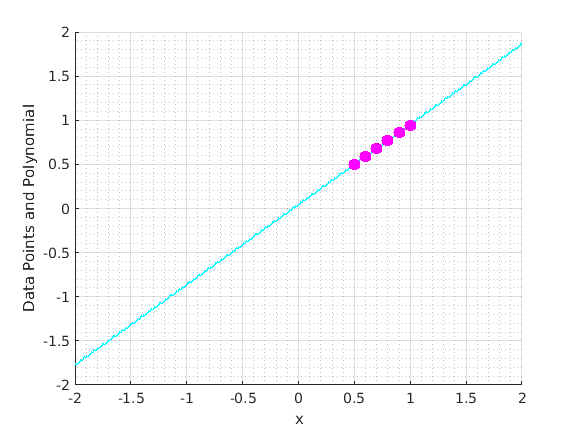

plotPoly(xData, yData, [-2,2], p1)

Find a quadratic interpolation (so order of poly = 2, and 3 data points around 0.72)

p2 = interpLagrange(xData(2:4), yData(2:4))

$$p2 = -0.1115\,x^{2}+1.07595\,x-0.01731$$

calc(p2, 0.72)

$$ans = 0.6995724$$

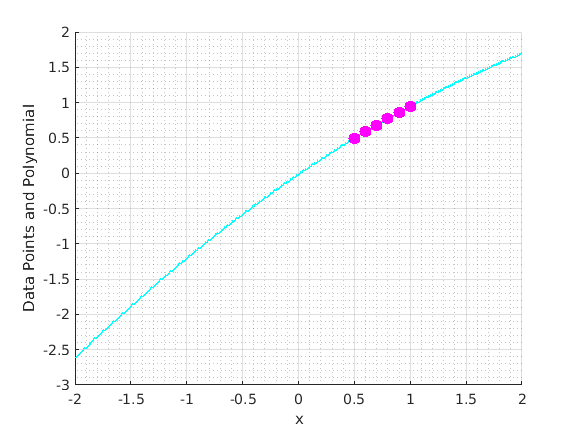

plotPoly(xData, yData, [-2,2], p2)

Find a cubic interpolation (so 4 data points around 0.72)

p3 = interpLagrange(xData(2:5), yData(2:5))

$$p3 = -0.04333333333\,x^{3}-0.0205\,x^{2}+1.012683333\,x-0.00275$$

calc(p3, 0.72)

$$ans = 0.69958072$$

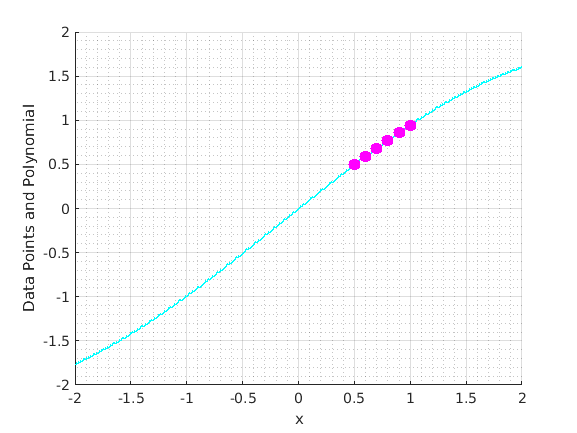

plotPoly(xData, yData, [-2,2], p3)

Find a quintic interpolation (so 6 data points around 0.72)

p5 = interpLagrange(xData, yData)

$$p5 = -0.06666666667\,x^{5}+0.2583333333\,x^{4}-0.4416666667\,x^{3}+0.2849166667\,x^{2}+0.8962733333\,x+0.01489$$

calc(p5, 0.72)

$$ans = 0.69958107712000000018603455831379$$

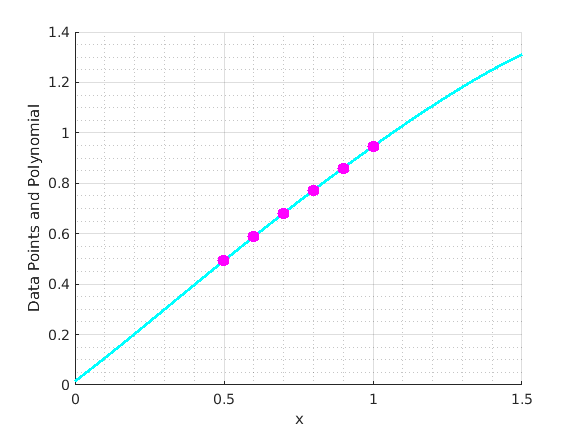

plotPoly(xData, yData, [0,1.5], p5)

polyfit(xData, yData, n), if n= length(y) = length(x) then we get the interpolation polynomial through the data points, else not. The lower order polys are not the same as the lower order interpolation polys .

cs = polyfit(xData, yData, 5) % n = highest order poly

cs =   -0.066666666667472   0.258333333336523  -0.441666666671605   0.284916666670398   0.896273333331958   0.014890000000198


p5

$$p5 = -0.06666666667\,x^{5}+0.2583333333\,x^{4}-0.4416666667\,x^{3}+0.2849166667\,x^{2}+0.8962733333\,x+0.01489$$

polyval(cs, xInterp) = evaluates the xInterp vector or value at the polynomial made by the coeffiicents called cs (output of polyfit , i.e)

polyval(cs, 0.72)

ans =    0.699581077120000


calc(p5, 0.72)

$$ans = 0.69958107712000000018603455831379$$